## Group Homework 4

Amanda Chang, Dokyun Kim, Jun Park

**1. Frequency domain filtering.** Do the following for 2 images of your choice **(10 points each for all sub-parts = 30 points total)**

- Apply low pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Apply high pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Add noise to your images. Does spatial domain filtering (median filtering, spatial domain gauss filter, etc.) work better to remove this noise or frequency domain filtering? 

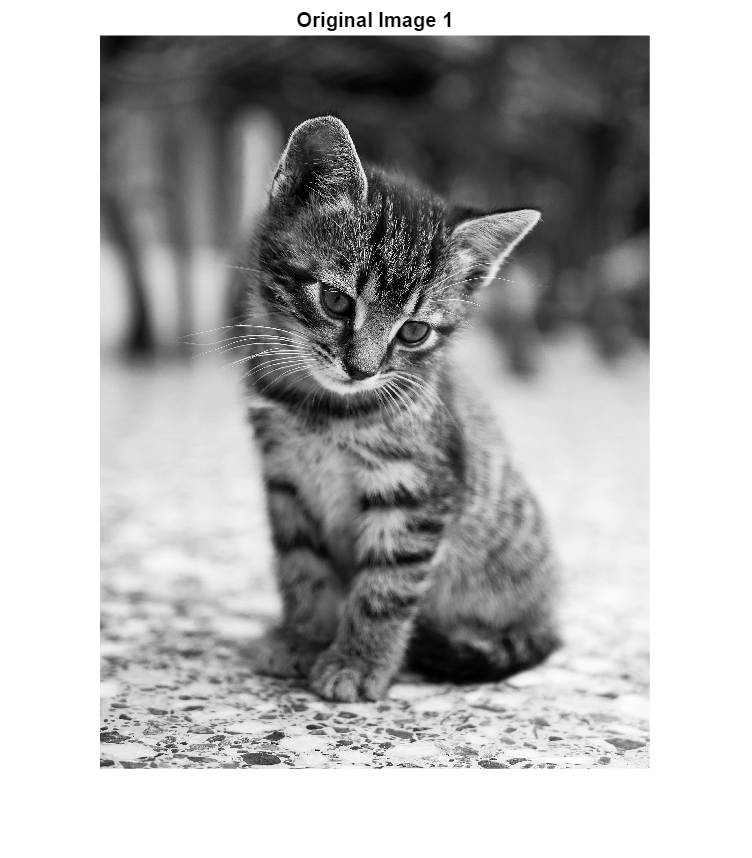

clear all;
close all;

img1 = rgb2gray(imread("../../pictures/cat.jpeg"));
img2 = rgb2gray(imread("../../pictures/dog.png"));
I1 = fftshift(fft2(img1));
I2 = fftshift(fft2(img2));

figure();
imshow(img1);
title("Original Image 1");

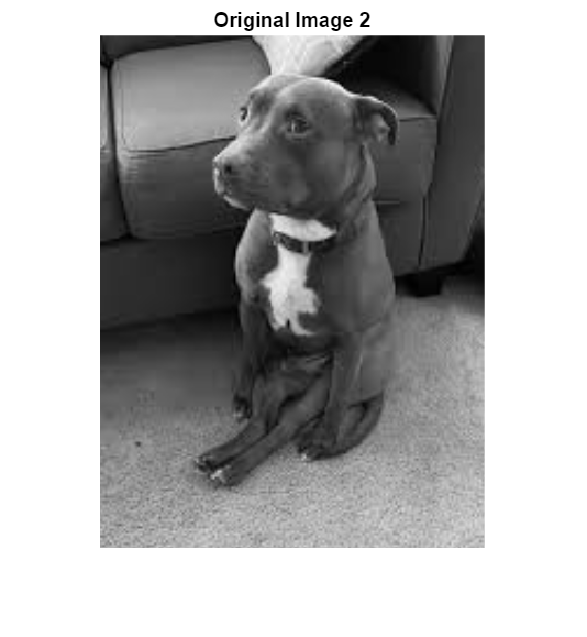

figure();
imshow(img2);
title("Original Image 2");

 Low pass filter

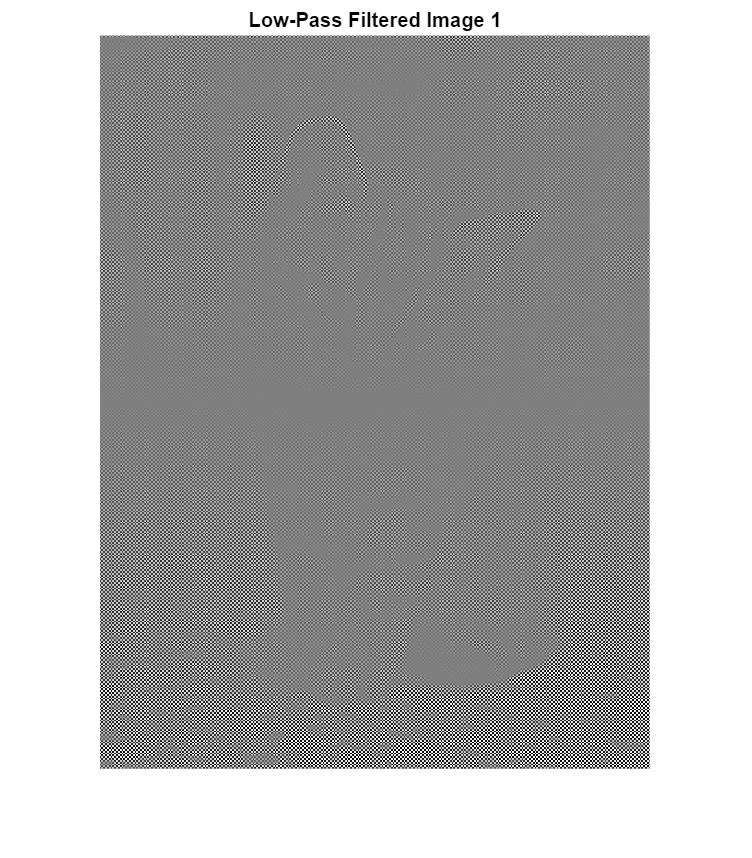

LPF1 = make_filter(I1, 100, 'lowpass');
LPF2 = make_filter(I2, 20, 'lowpass');

I1_LPF = (ifft2(I1 .* LPF1));
I2_LPF = (ifft2(I2 .* LPF2));

figure();
imshow(real(I1_LPF), []);
title('Low-Pass Filtered Image 1');

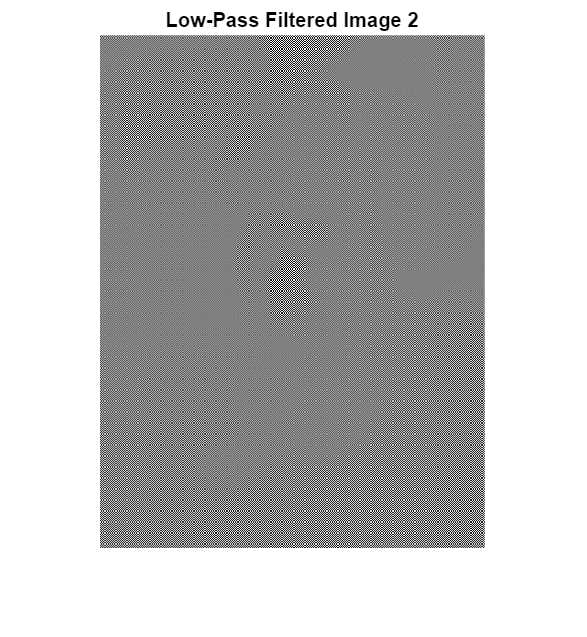


figure();
imshow(real(I2_LPF), []);
title('Low-Pass Filtered Image 2');

High pass filter

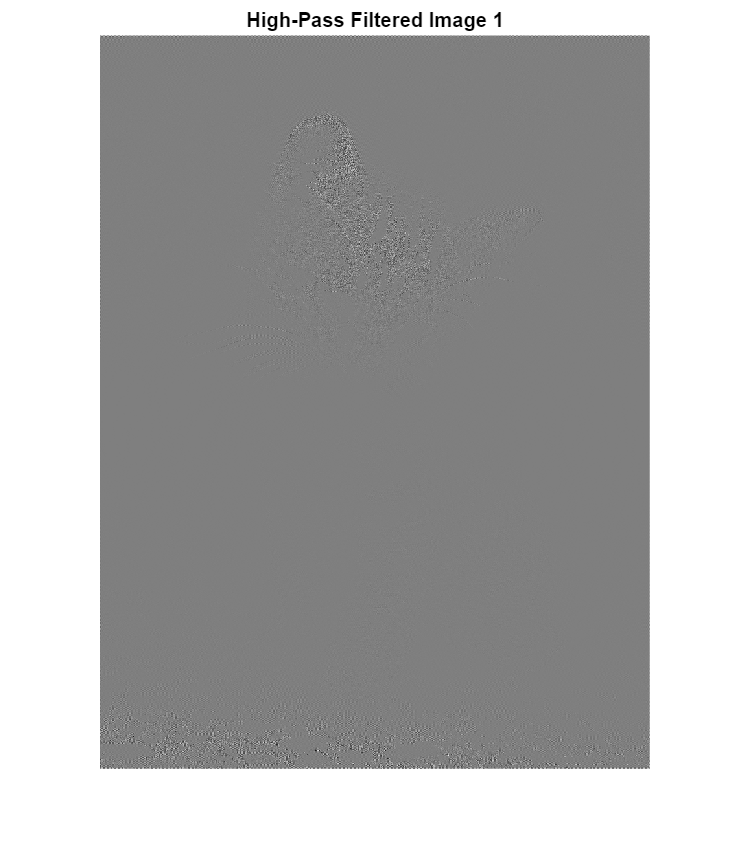

HPF1 = make_filter(I1, 100, 'highpass');
HPF2 = make_filter(I2, 20, 'highpass');

I1_HPF = (ifft2(I1 .* HPF1));
I2_HPF = (ifft2(I2 .* HPF2));

figure();
imshow(real(I1_HPF), []);
title('High-Pass Filtered Image 1');

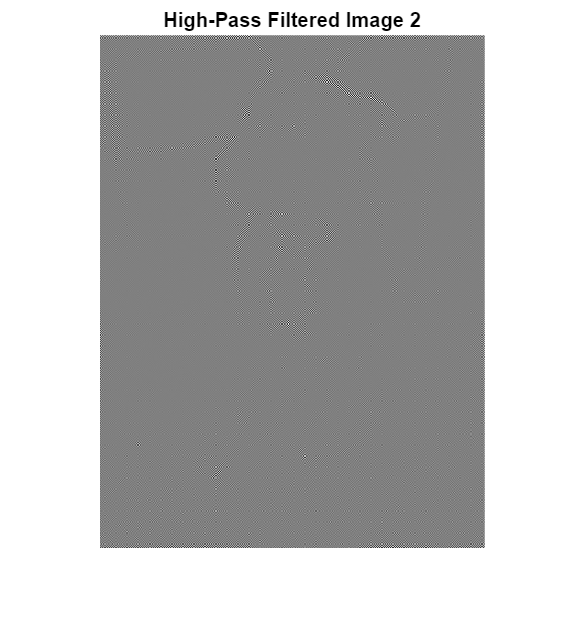

figure();
imshow(real(I2_HPF), []);
title('High-Pass Filtered Image 2');

Spatial filter vs. Frequency filter

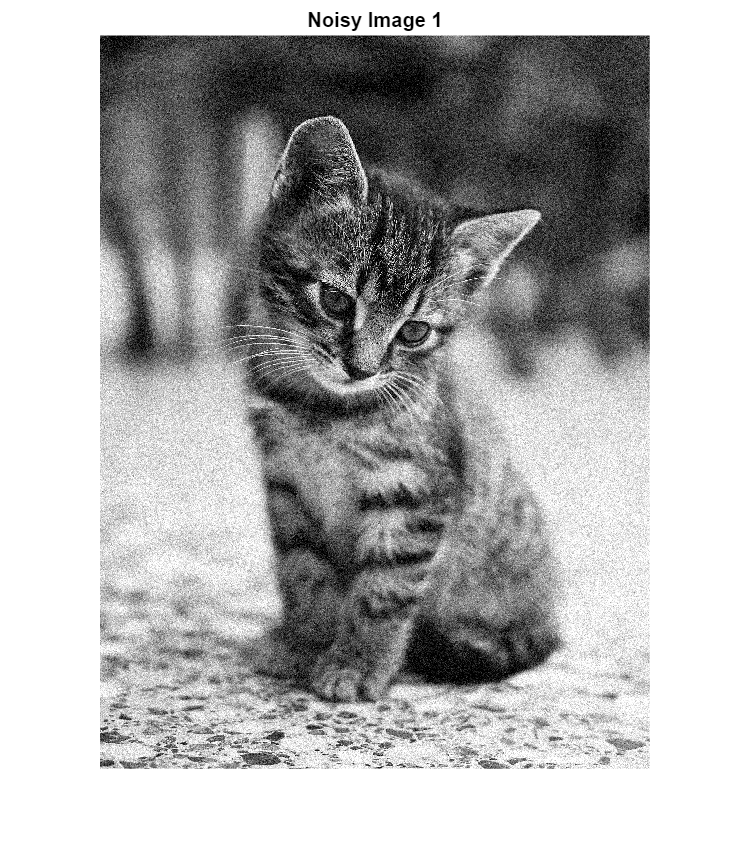

noised1 = imnoise(img1, 'gaussian', 0, 0.01);
noised2 = imnoise(img2, 'gaussian', 0, 0.01);

% Display noisy images
figure();
imshow(noised1);
title('Noisy Image 1');

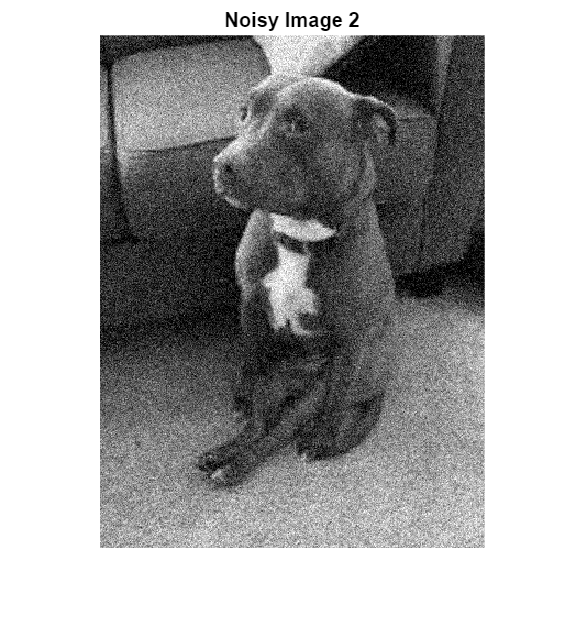

figure();
imshow(noised2);
title('Noisy Image 2');

**2. Deconvolution and Deblurring. **MATLAB and other programming platforms allow you to do a blind deconvolution or use some pre-designed functions to achieve deblurring. Try out the given sample code [trydeconv.m](https://canvas.olin.edu/courses/819/files/186973?wrap=1)[ Download trydeconv.m](https://canvas.olin.edu/courses/819/files/186973/download?download_frd=1)on some of your images. What are the pros and cons of these pre-designed functions? Pre-designed functions estimate the blurring kernel for you. Research and explain any two methods of estimating a deblurring kernel without using pre-designed functions? You can use any material available to do your research – youtube videos, research papers, tutorials – whatever your group chooses. **(30 points).** (might be helpful to review [MATLAB summary of blind deconvolutionLinks to an external site.](https://www.mathworks.com/help/images/ref/deconvblind.html)).

**3. Histogram equalization. **Use histogram equalization as an image enhancement technique on two images of your choice. If you used inbuilt functions (e.g. histeq in MATLAB, or cv2.equalizeHist() in OpenCV), did you see any limitations of these inbuilt functions? If yes, what are they? **(10 points). **(sample histogram equalization code: [imenhance.m](https://canvas.olin.edu/courses/819/files/186985?wrap=1)[Download imenhance.m](https://canvas.olin.edu/courses/819/files/186985/download?download_frd=1)

**4. Some more filtering. **You are provided with a code ‘[Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868?wrap=1)[ Download Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868/download?download_frd=1)’). It implements 3 types of low pass filters in frequency domain – ideal, butterworth and gaussian. Run this code for an image of your choice. Comment on the effects of these filters in your image. Feel free to play around with parameters and those changes to your comments. **(10 points).**

function filter = make_filter(I, radius, type)
    [rows, cols] = size(I);
    crow = round(rows/2); % Center of circle
    ccol = round(cols/2); % Center of circle
    
    % Create a meshgrid for the filter
    [x, y] = meshgrid(1:cols, 1:rows);
    distance = sqrt((x - ccol).^2 + (y - crow).^2);

    if strcmp(type, "lowpass")
        filter = double(distance <= radius);
    elseif strcmp(type, "highpass")
        filter = double(distance > radius);
    else
        disp("Invalid Filter Type");
    end
end